## Test function: Chained Wood function - 10^3

% Dimension n (multiple of 4)
n = 10^3;  % 10^3;

% Initializations
f = @(x) 0;
x0 = zeros(n, 1);

% Chained Wood function
for j = 1 : (n - 2)/2
    f_1 = @(x) 100*(x(2*j-1, :).^2 - x(2*j, :)).^2 + ...
        (x(2*j-1, :) - 1).^2 + ...
        90*(x(2*j+1, :).^2 - x(2*j+2, :)).^2 + ...
        (x(2*j+1, :) - 1).^2 + ...
        10*(x(2*j, :) + x(2*j+2, :) - 2).^2  + ...
        (1/10)*(x(2*j, :) - x(2*j+2, :)).^2;  % Wood function (j=1)
    f = @(x) f(x) + f_1(x);  % Chained Wood function
end

% Starting point x0
for j = 1 : n
    if j <= 4
        if mod(j, 2) == 1
            x0(j) = -3;
        else
            x0(j) = -1;
        end
    else
        if mod(j, 2) == 1
            x0(j) = -2;
        else
            x0(j) = 0;
        end
    end
end

% Expected solution
x_sol = ones(1, n)'; 

% Gradient
gradf = @(x) chainedwood_grad(x);

### Parameters 

load('forcing_terms.mat')

kmax = 500;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 10;  % initial step-length
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    500       5        1e-08       10      0.0001    0.5     800 


## Steepest descent method - 10^3

[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt(x0, x_sol, f, gradf, alpha0, step_k, kmax, tolgrad, c1, rho, btmax);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     0.88187      1  
     0.77686      1  
       1.114      1  
      1.2409      1  
    -0.83837      1  
     0.71428      1  
      -1.058      1  
      1.1297      1  


tail(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

    -0.98026      1  
     0.97155      1  
    -0.95474      1  
     0.92231      1  
    -0.98434      1  
     0.97952      1  
    -0.95164      1  
     0.91705      1  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
      fk       k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    ___    ______________    ___________    _______________    __________    _____________

    373.79    500        50579           0.76647          0.51184          373.79          1.53     


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

       1500      -0.22333       0.053514  
     864.61      -0.83462       0.066561  
     523.23      -0.76905       0.077519  
     443.74      -0.66528       0.089995  
     409.24       -1.3246         0.1026  
     397.08      -0.86883        0.11659  
     381.81       -7.1543        0.13346  
     377.01        1.9928        0.14872  


tail(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

      373.8       0.73108        1.4332   
      373.8        8.2972        1.4478   
      373.8       0.16234        1.4602   
      373.8        1.0052        1.4741   
      373.8       0.99326        1.4873   
      373.8        9.0833         1.502   
     373.79       0.24355        1.5181   
     373.79           4.7          1.53   


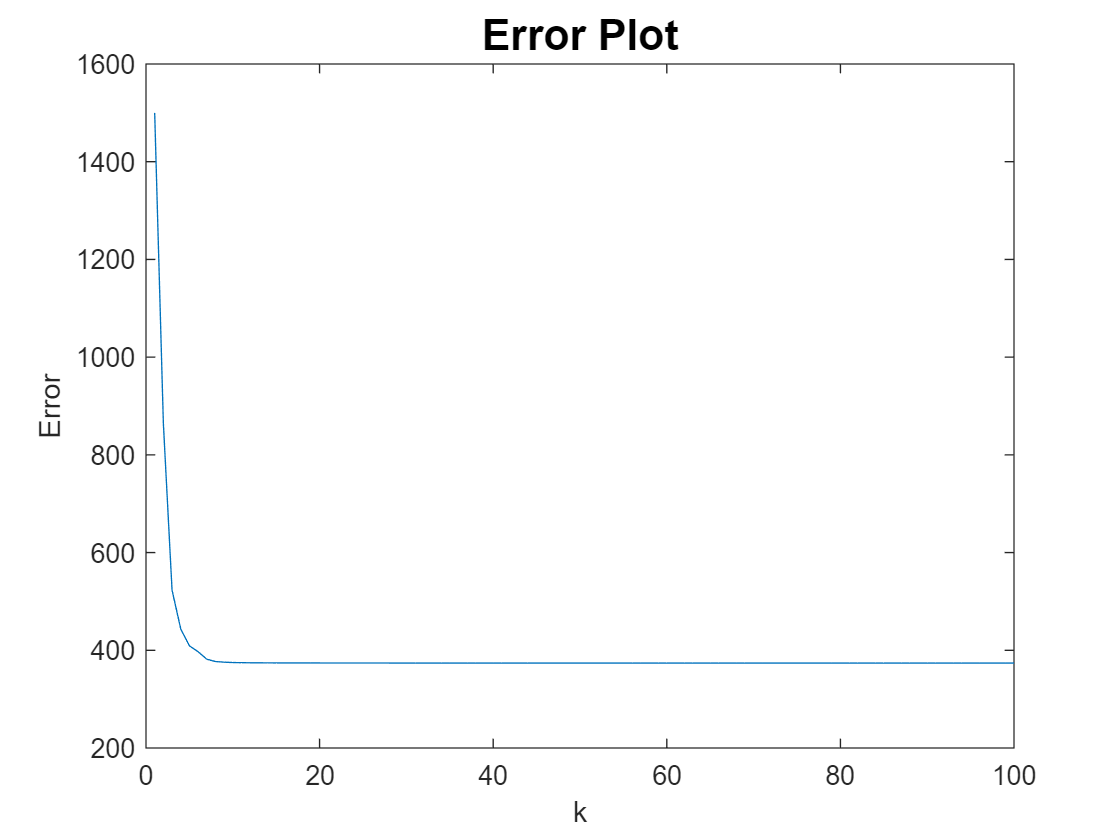

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

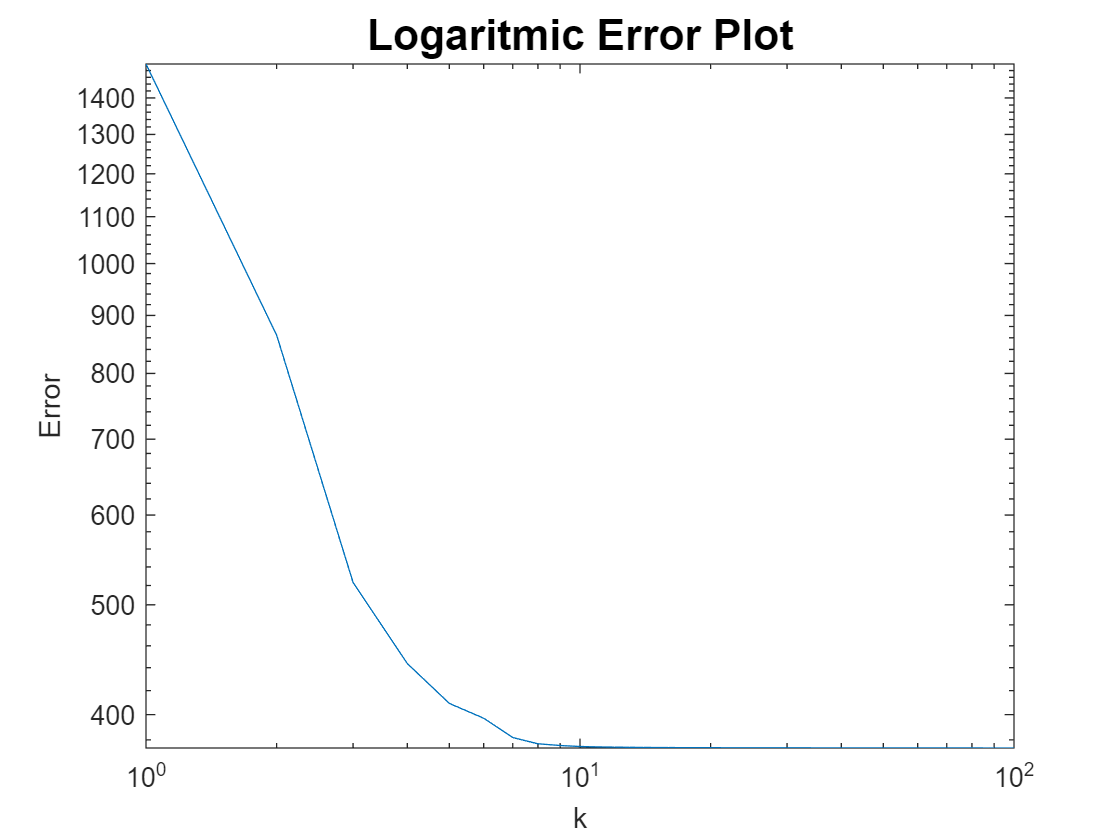

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

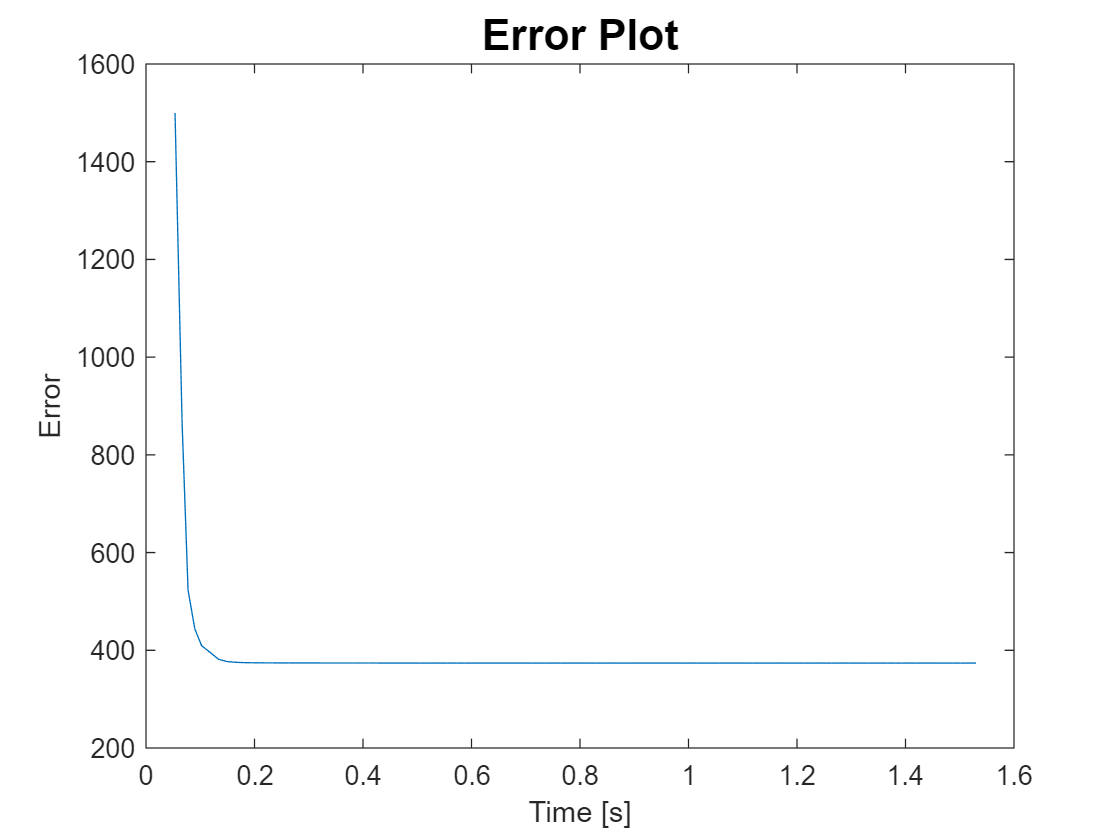

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

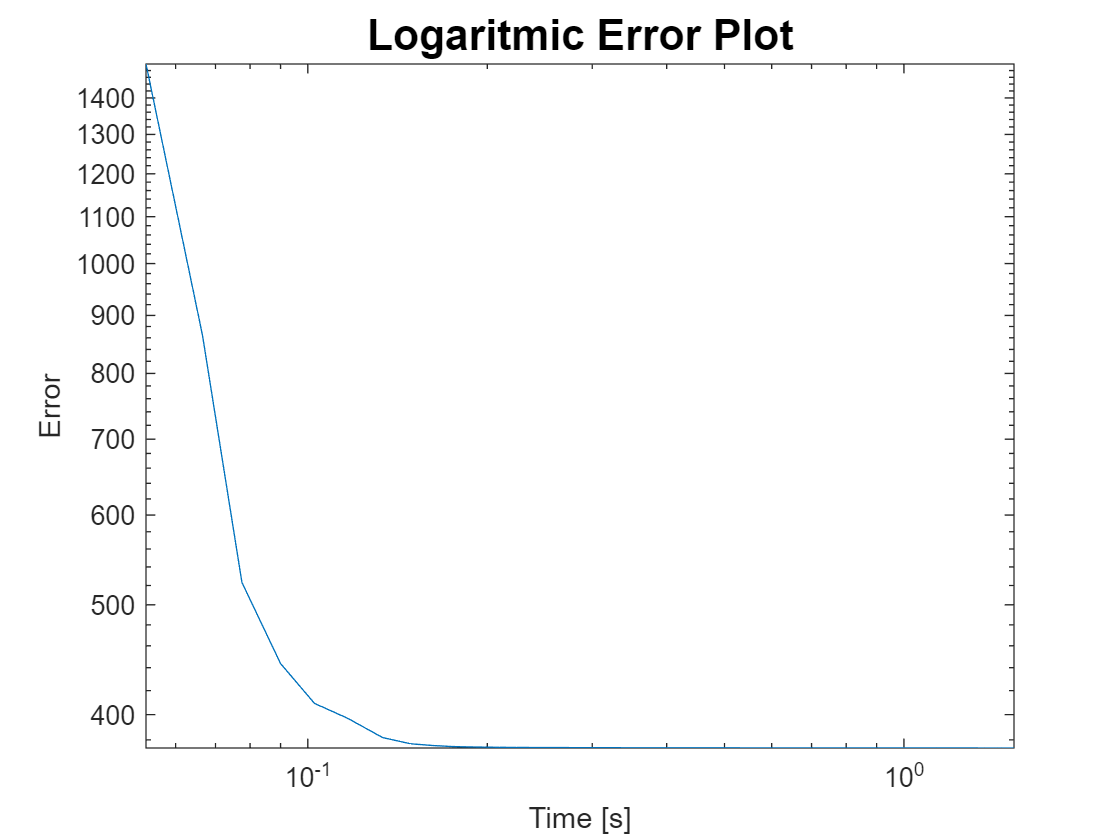

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Inexact Newton method - 10^3

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-1;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0    c1     rho    btmax
    ____    ______    _______    ______    ___    ___    _____

    100       5        1e-08       10      0.1    0.5     800 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, big_k, pk_itcount, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck(x0, x_sol, f, gradf, Hessf, step_k, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

    -0.99948      1  
       1.009      1  
    -0.93653      1  
     0.88796      1  
     -1.0005      1  
      1.0116      1  
    -0.93602      1  
     0.88702      1  


tail(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

    -0.98013      1  
     0.97129      1  
     -0.9577      1  
     0.92794      1  
     -0.9793      1  
     0.96968      1  
    -0.95806      1  
     0.92921      1  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×8 table
      fk       k     pk_itcount    gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    ___    __________    ______________    ___________    _______________    __________    _____________

    385.97    100        67            50579          0.090876         0.038009          385.97         0.4836    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     692.48         0.518       0.032067  
     386.02      -0.27731       0.054372  
     385.97         2.883       0.081136  
     385.97           NaN         0.1094  
     385.97           NaN        0.13309  
     385.97           NaN        0.15983  
     385.97           NaN        0.18685  
     385.97           NaN        0.21005  


tail(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     385.97         NaN          0.32854  
     385.97         NaN          0.35133  
     385.97         NaN          0.37309  
     385.97         NaN          0.39382  
     385.97         NaN          0.41827  
     385.97         NaN          0.44143  
     385.97         NaN          0.46294  
     385.97         NaN           0.4836  


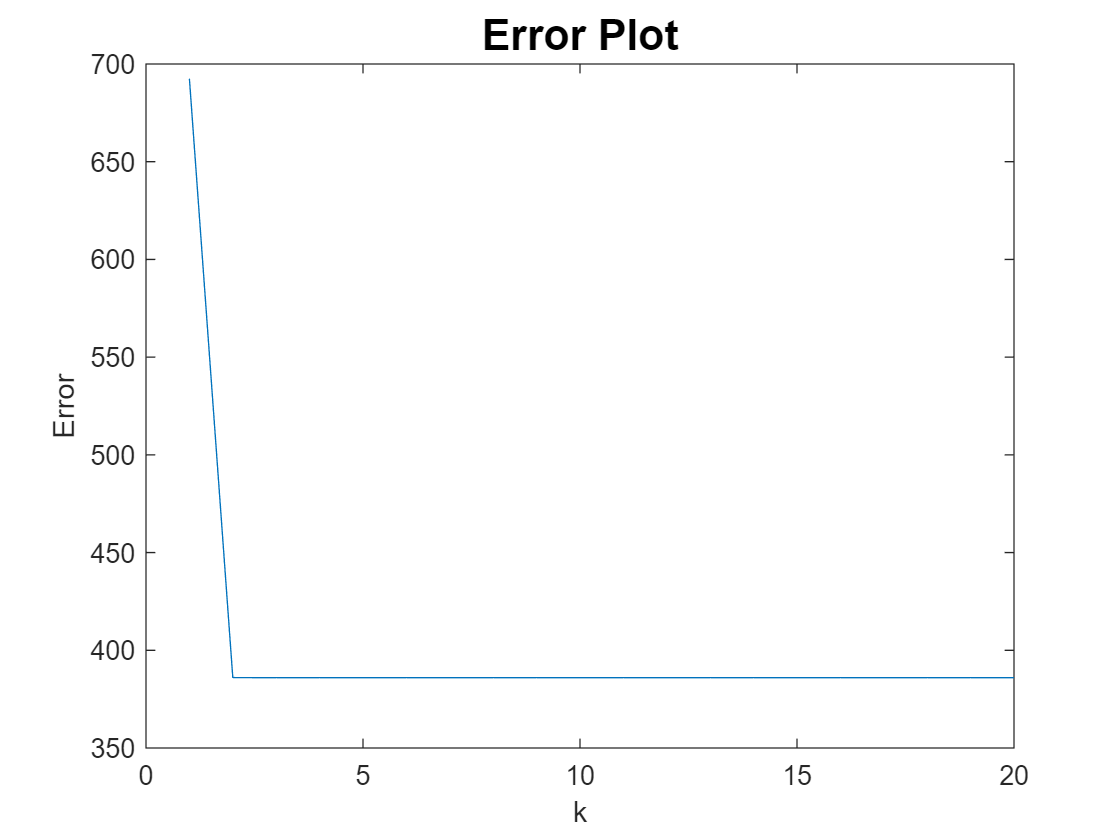

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

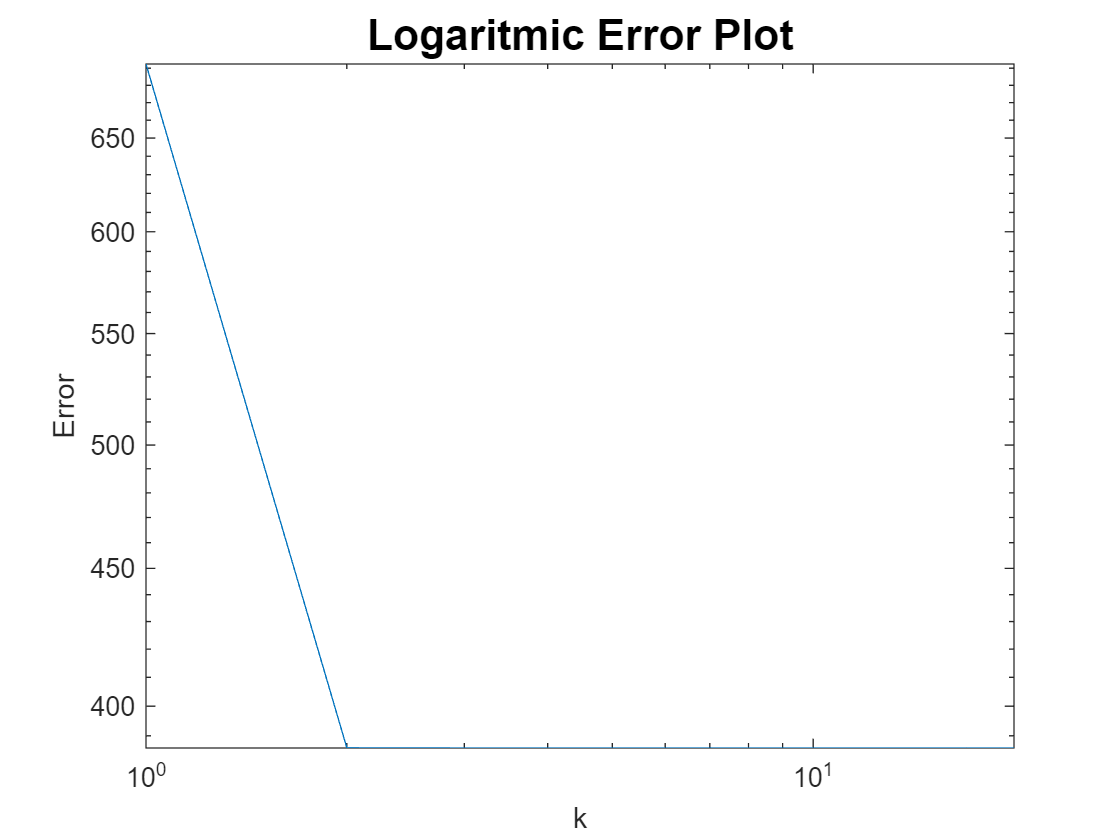

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

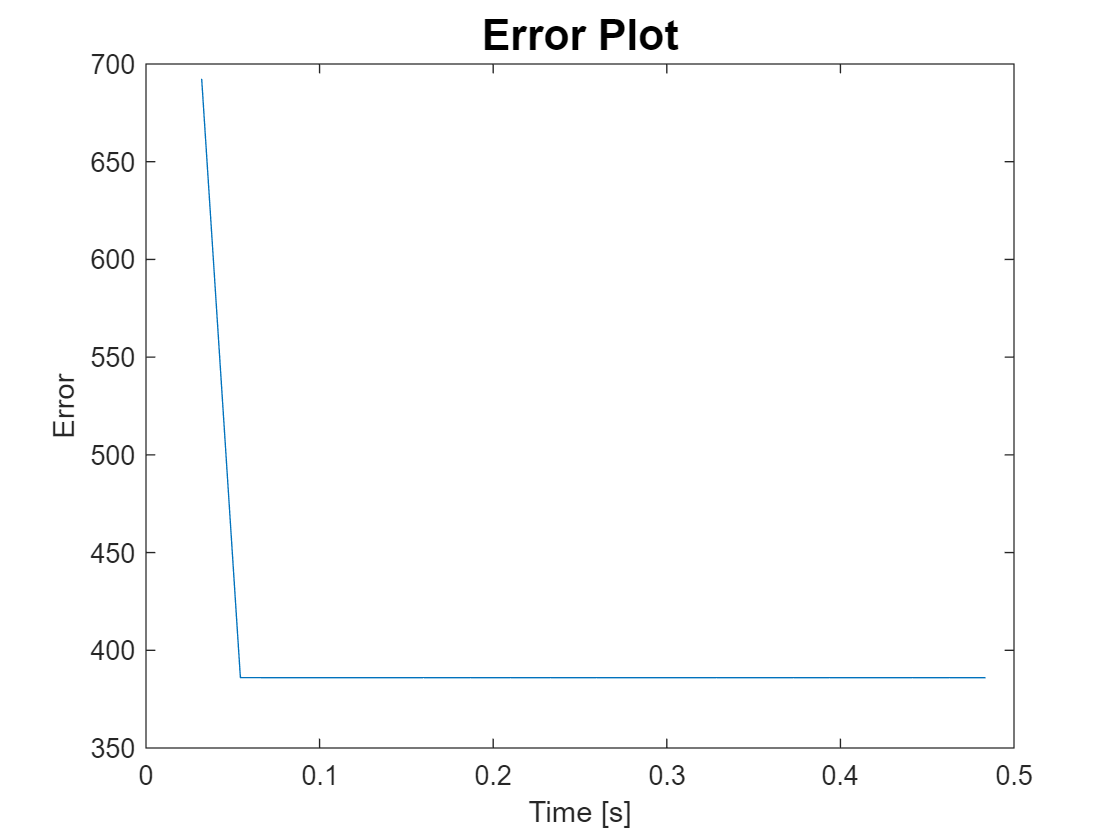

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

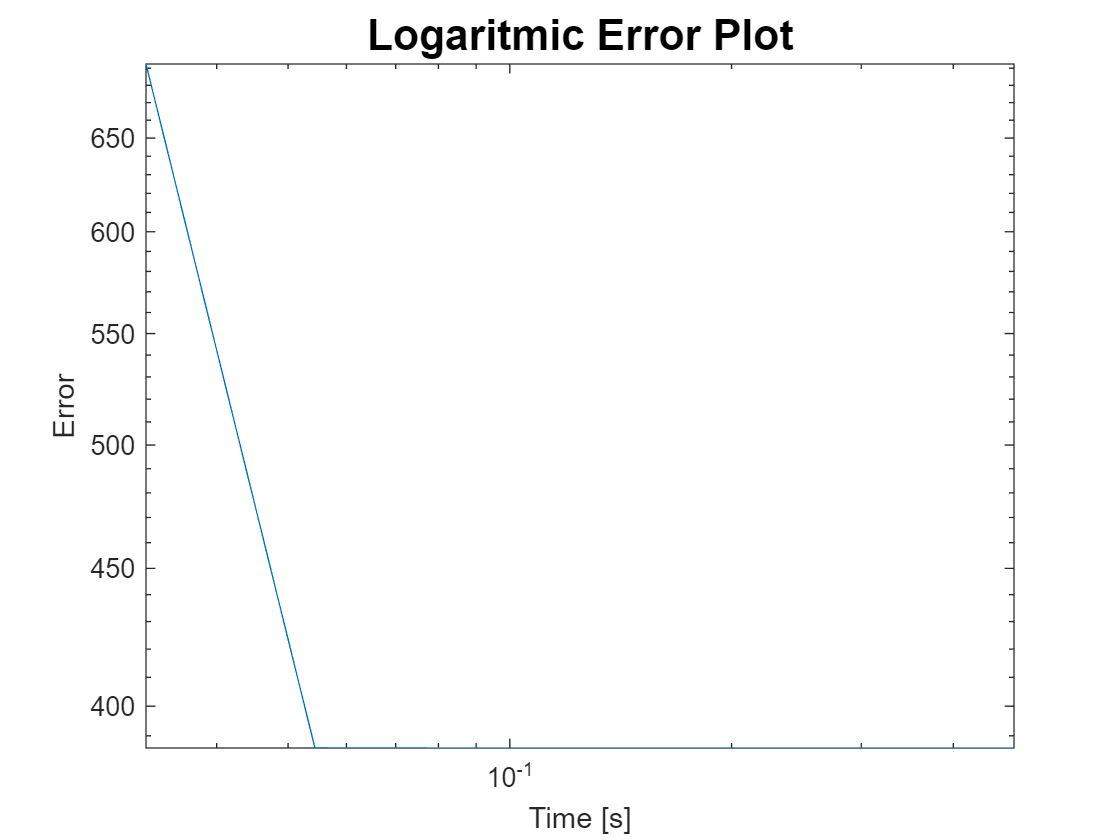

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Modified Newton method - 10^3

% Dimension n (multiple of 4)
n = 10^3;  % 10^3;

% Initializations
f = @(x) 0;
x0 = zeros(n, 1);

% Chained Wood function
for j = 1 : (n - 2)/2
    f_1 = @(x) 100*(x(2*j-1, :).^2 - x(2*j, :)).^2 + ...
        (x(2*j-1, :) - 1).^2 + ...
        90*(x(2*j+1, :).^2 - x(2*j+2, :)).^2 + ...
        (x(2*j+1, :) - 1).^2 + ...
        10*(x(2*j, :) + x(2*j+2, :) - 2).^2  + ...
        (1/10)*(x(2*j, :) - x(2*j+2, :)).^2;  % Wood function (j=1)
    f = @(x) f(x) + f_1(x);  % Chained Wood function
end

% Starting point x0 (more easy)
x0 = 2*ones(1, n)';

% Expected solution
x_sol = ones(1, n)'; 

% Gradient
gradf = @(x) chainedwood_grad(x);

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-1;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax    step_k    tolgrad    c1     rho    btmax
    ____    ______    _______    ___    ___    _____

    100       5        1e-08     0.1    0.1     800 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = 0.01;  % sqrt(eps)*norm(x0);
[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, ...
    totalTimeCost, timeCostseq] = modnewton_bcktrck(x0,x_sol,f,gradf,...
    Hessf,step_k,kmax,tolgrad,c1,rho,btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  


tail(results_0, 8)

ans = 8×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
        fk        k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    __________    __    ______________    ___________    _______________    __________    _____________

    2.8824e-20    13        21722         6.5414e-10       2.0779e-10       2.4571e-08       0.25868   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 2×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        58.788      1.6662         0.14828  
    2.4571e-08      1.2123         0.25868  


tail(results_2, 8)

ans = 2×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        58.788      1.6662         0.14828  
    2.4571e-08      1.2123         0.25868  


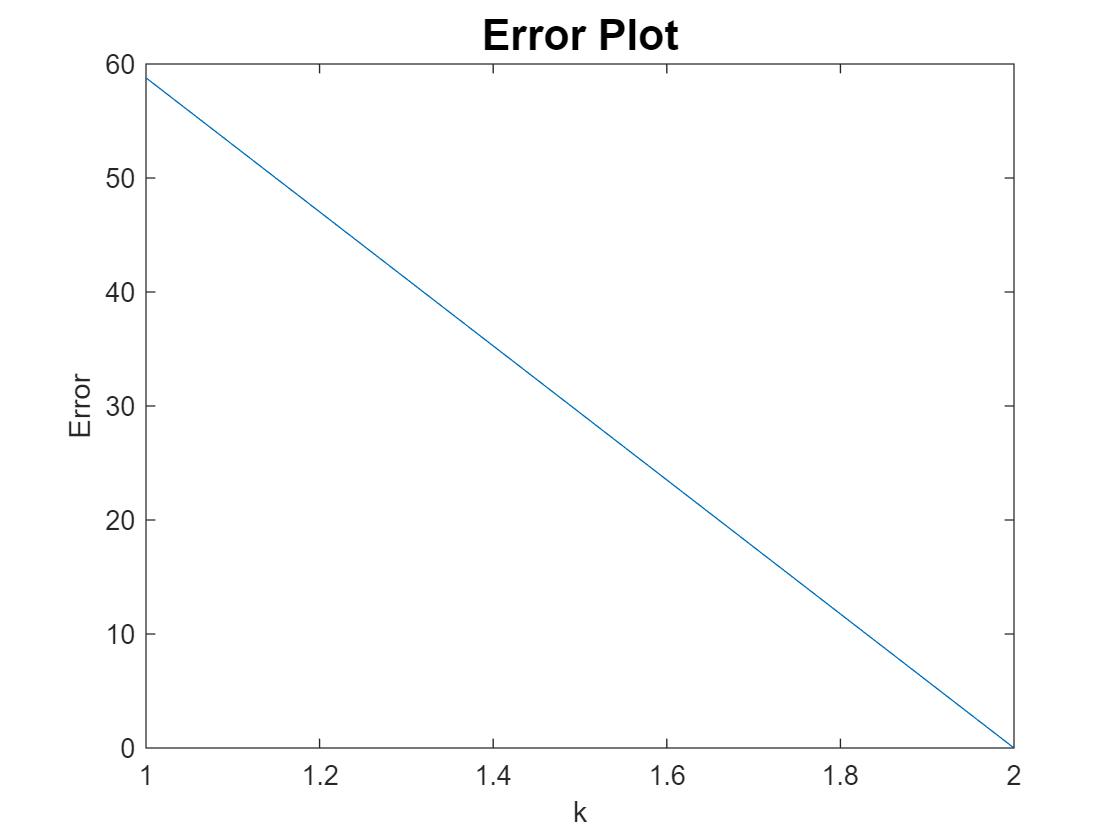

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

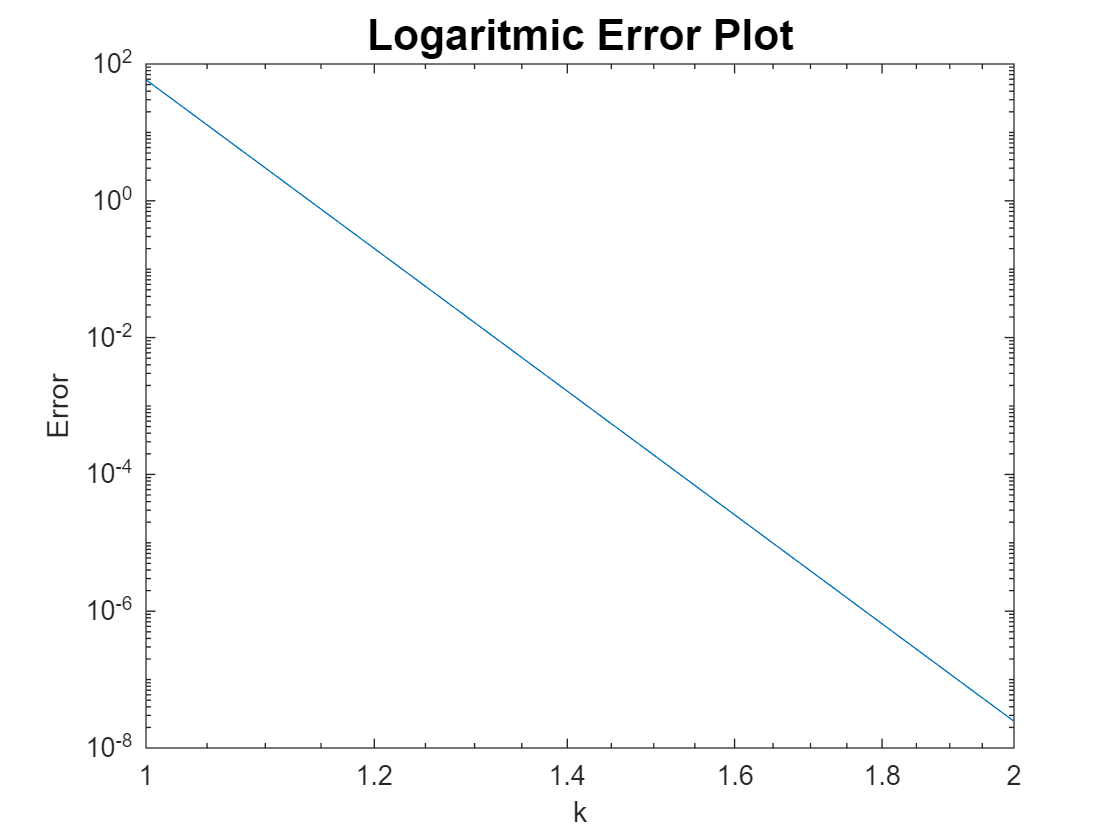

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

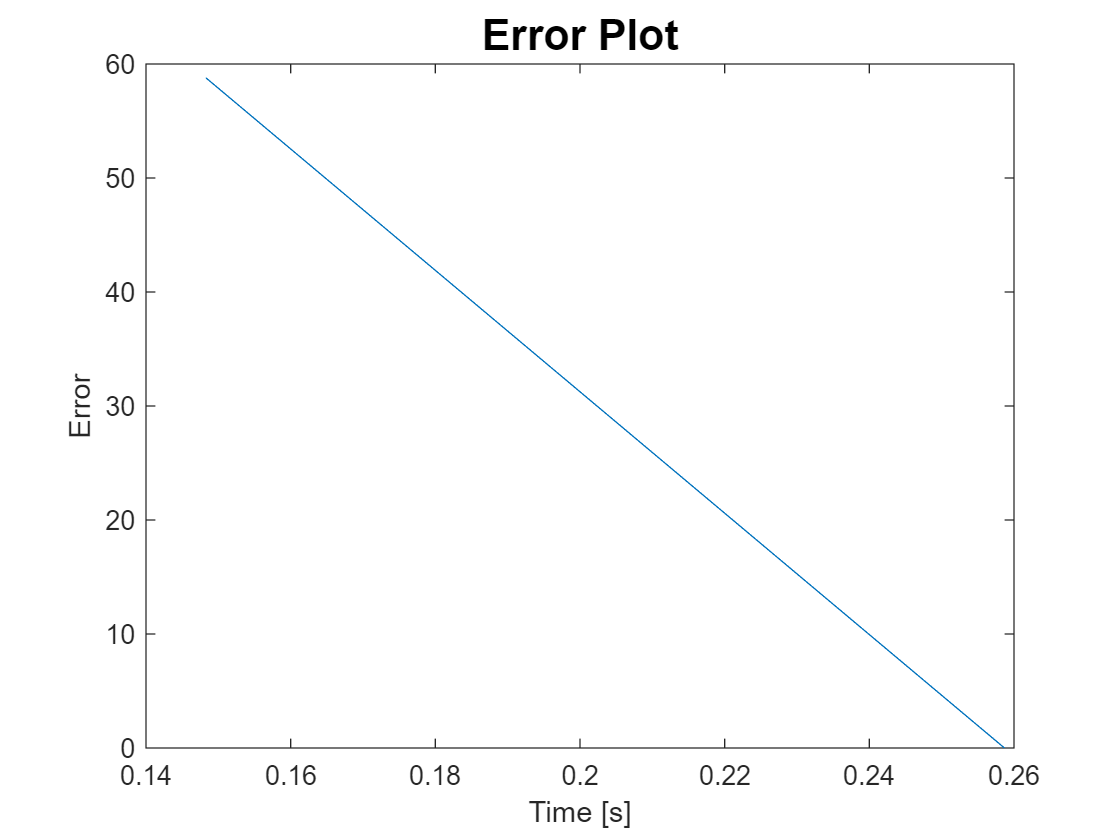

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

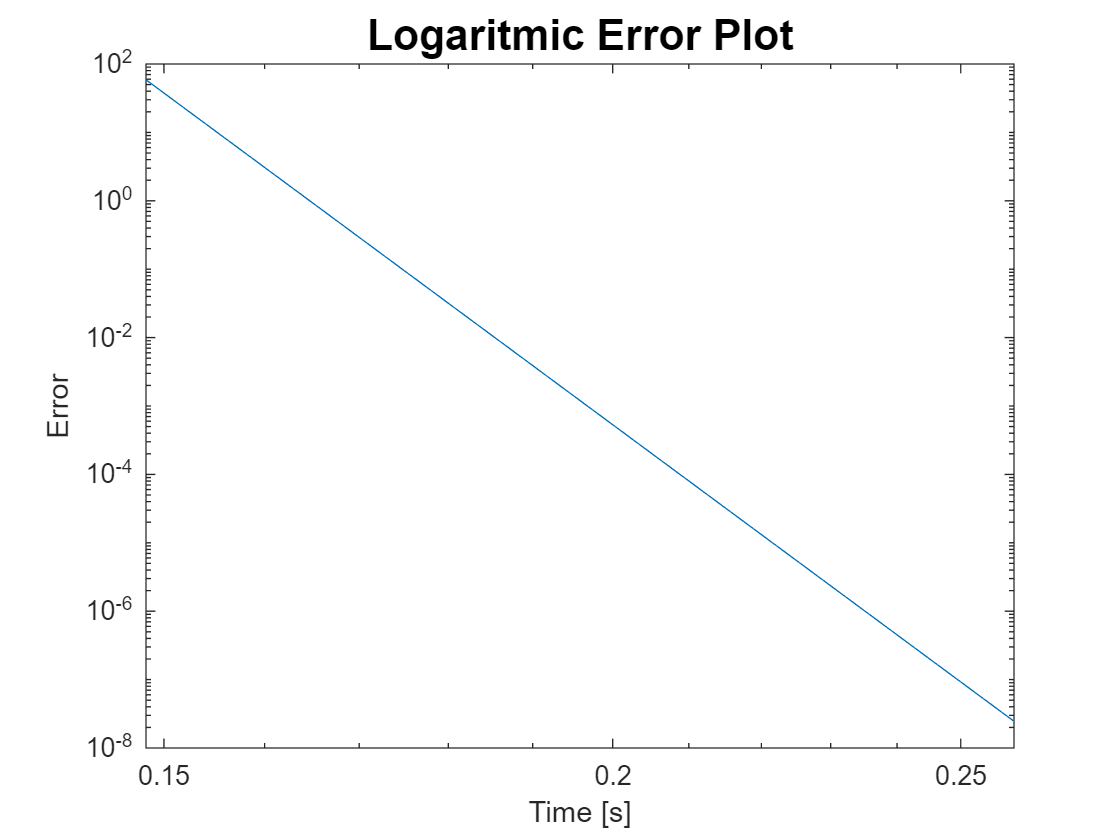

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

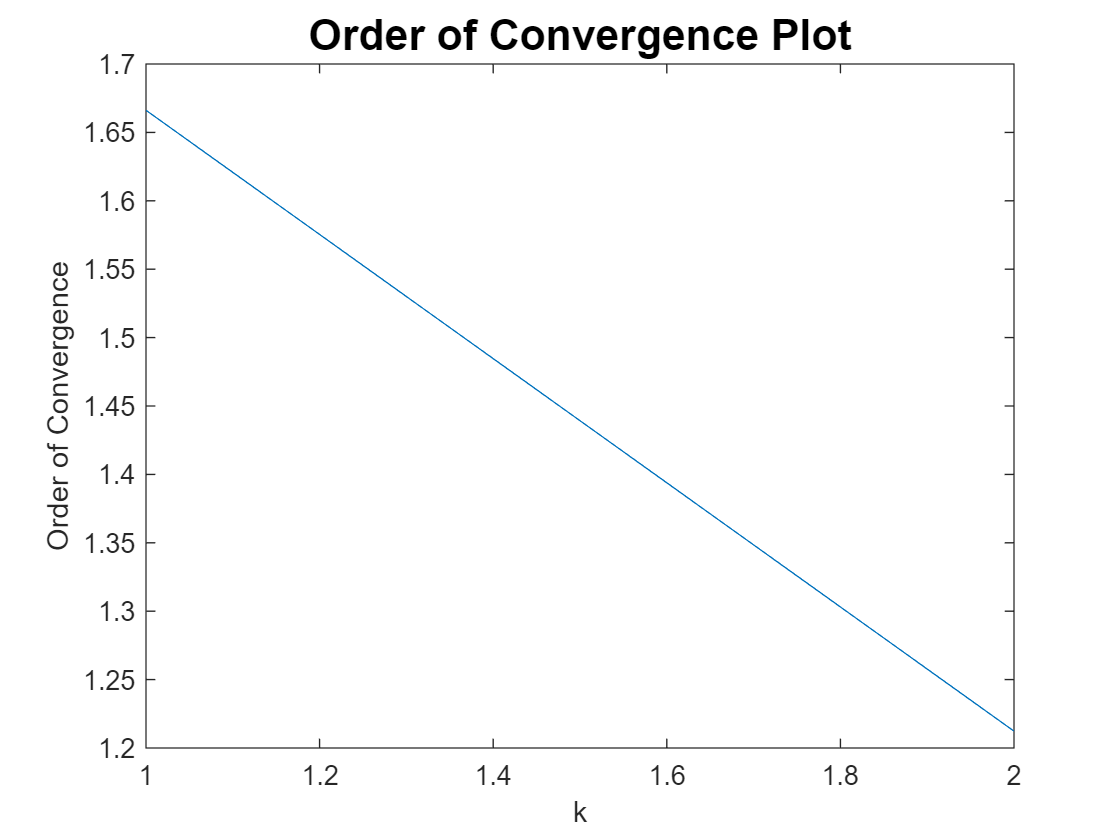

plot(1:big_k, ordconv_seq)
title('Order of Convergence Plot','FontSize',16)
xlabel('k')
ylabel('Order of Convergence')

## Test function: Chained Wood function - 10^4

% Dimension n (multiple of 4)
n = 10^4;  % 10^4;

% Initializations
f = @(x) 0;
x0 = zeros(n, 1);

% Chained Wood function
for j = 1 : (n - 2)/2
    f_1 = @(x) 100*(x(2*j-1, :).^2 - x(2*j, :)).^2 + ...
        (x(2*j-1, :) - 1).^2 + ...
        90*(x(2*j+1, :).^2 - x(2*j+2, :)).^2 + ...
        (x(2*j+1, :) - 1).^2 + ...
        10*(x(2*j, :) + x(2*j+2, :) - 2).^2  + ...
        (1/10)*(x(2*j, :) - x(2*j+2, :)).^2;  % Wood function (j=1)
    f = @(x) f(x) + f_1(x);  % Chained Wood function
end

% Starting point x0
for j = 1 : n
    if j <= 4
        if mod(j, 2) == 1
            x0(j) = -3;
        else
            x0(j) = -1;
        end
    else
        if mod(j, 2) == 1
            x0(j) = -2;
        else
            x0(j) = 0;
        end
    end
end

% Expected solution
x_sol = ones(1, n)'; 

% Gradient
gradf = @(x) chainedwood_grad(x);

### Parameters 

load('forcing_terms.mat')

kmax = 1000;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
alpha0 = 10;  % initial step-length
c1 = 1e-1;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0    c1     rho    btmax
    ____    ______    _______    ______    ___    ___    _____

    1000      5        1e-08       10      0.1    0.5     500 


## Steepest descent method - 10^4

[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    steepest_desc_bckt(x0, x_sol, f, gradf, alpha0, step_k, kmax, tolgrad, c1, rho, btmax);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     0.69781      1  
     0.48496      1  
      1.2409      1  
      1.5421      1  
    -0.61535      1  
     0.39248      1  
     -1.1926      1  
      1.4321      1  


tail(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

    -0.99677      1  
      1.0041      1  
    -0.93595      1  
      0.8869      1  
     -1.0031      1  
      1.0167      1  
    -0.93137      1  
     0.87902      1  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
      fk       k      gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    ____    ______________    ___________    _______________    __________    _____________

    373.51    1000        50579           1.3796           1.1322           373.51         2.7016    


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     1444.9        -1.5636      0.011795  
     846.29        0.54867       0.02225  
     720.59      -0.035706      0.033993  
     463.28         1.5136      0.046534  
     442.53        0.85447      0.057865  
     424.25         1.0806       0.06981  
     410.61         2.3952      0.081626  
     400.65         1.5194      0.093331  


tail(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     373.52        5.5291        2.6108   
     373.52        0.0776        2.6305   
     373.52        6.0747        2.6423   
     373.52       0.21477        2.6548   
     373.51        4.3381        2.6667   
     373.51       0.33388        2.6776   
     373.51        1.2394        2.6893   
     373.51       0.89615        2.7016   


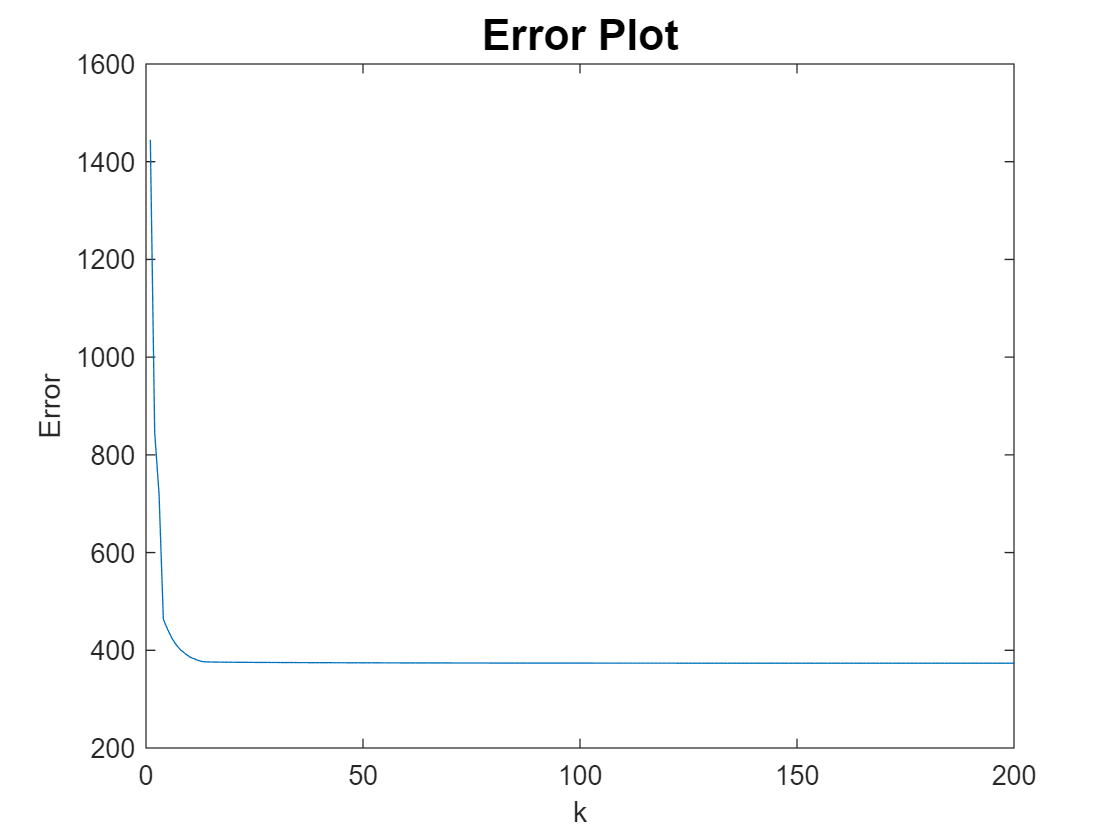

plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

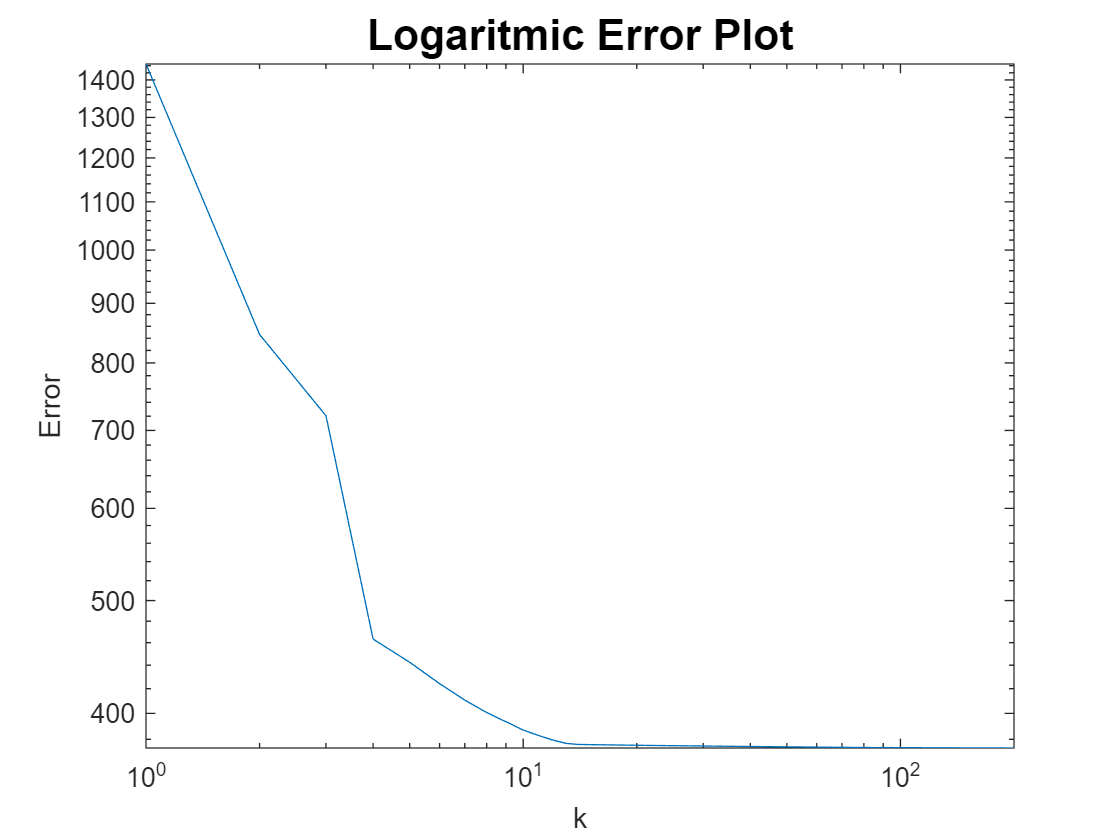

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

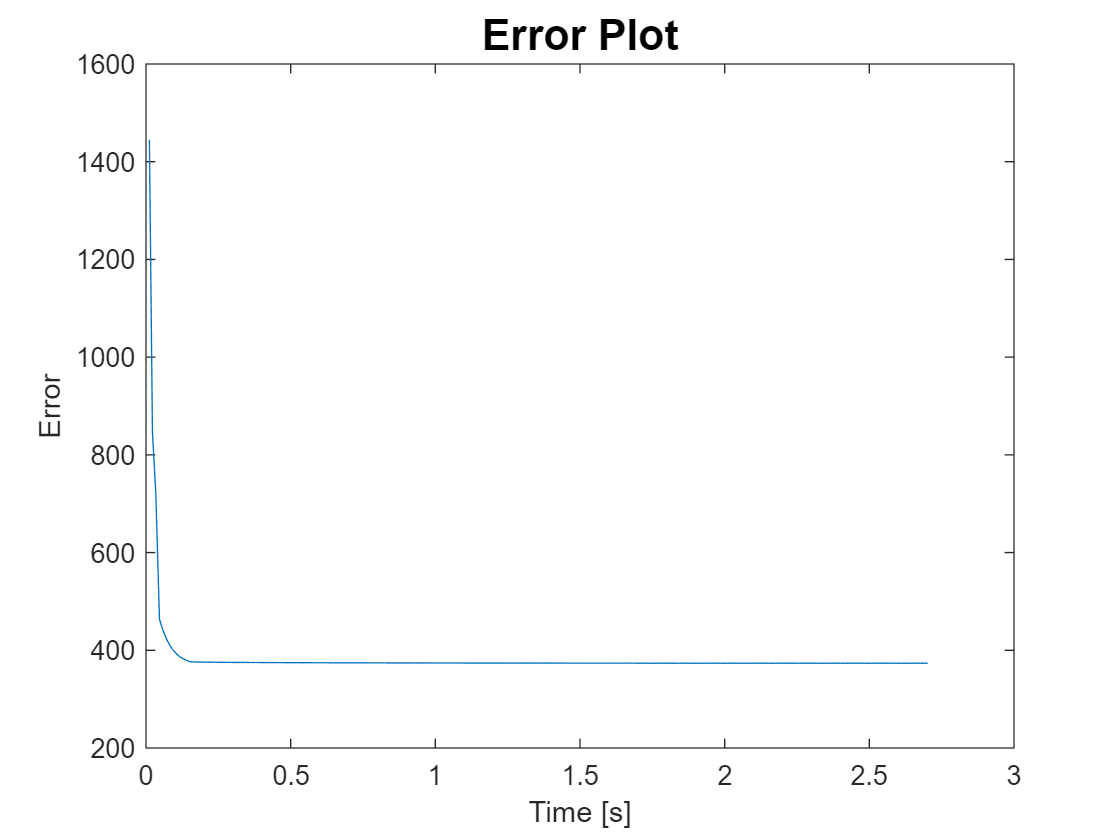

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

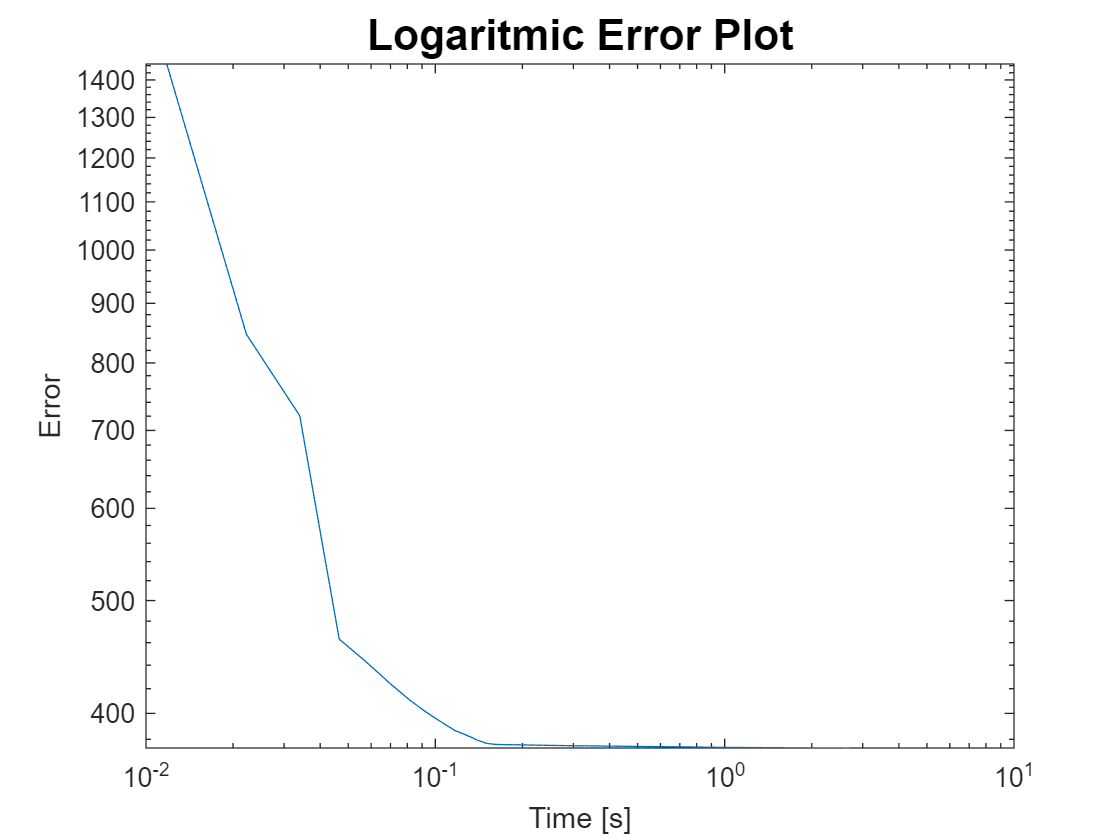

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Inexact Newton method - 10^4

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-4;  % factor of the Armijo condition
rho = 0.5;  % fixed factor used for reducing alpha0
btmax = 500;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, alpha0, c1, rho, btmax)

parameters = 1×7 table
    kmax    step_k    tolgrad    alpha0      c1      rho    btmax
    ____    ______    _______    ______    ______    ___    _____

    100       5        1e-08       10      0.0001    0.5     500 


% gradf = @(x) 0;
Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = sqrt(eps);
fterms = fterms_lin;
pcg_maxit = 50;  % 100
[xk, fk, gradfk_norm, k, big_k, pk_itcount, err_fseq, ordconv_seq, totalTimeCost, timeCostseq] = ...
    innewton_bcktrck(x0, x_sol, f, gradf, Hessf, step_k, kmax, ...
    tolgrad, c1, rho, btmax, FDgrad, FDHess, h, fterms, pcg_maxit);

*** Iterations overcome maximum number of iterations ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

     -1.0001      1  
      1.0102      1  
    -0.93619      1  
     0.88733      1  
     -1.0001      1  
      1.0107      1  
    -0.93572      1  
     0.88646      1  


tail(results_0, 8)

ans = 8×2 table
       xk       x_sol
    ________    _____

    -0.98003      1  
     0.97109      1  
    -0.95752      1  
      0.9276      1  
    -0.97947      1  
        0.97      1  
    -0.95783      1  
      0.9288      1  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, pk_itcount, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×8 table
      fk       k     pk_itcount    gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    ______    ___    __________    ______________    ___________    _______________    __________    _____________

    385.97    100        67            50579           0.10684         0.038176          385.97         0.44103   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     692.48         0.518       0.024308  
     386.02      -0.27731       0.044362  
     385.97         2.883       0.068735  
     385.97           NaN       0.092802  
     385.97           NaN        0.11516  
     385.97           NaN        0.13738  
     385.97           NaN        0.15926  
     385.97           NaN        0.18109  


tail(results_2, 8)

ans = 8×3 table
    err_fseq    ordconv_seq    timeCostseq
    ________    ___________    ___________

     385.97         NaN          0.29083  
     385.97         NaN          0.31177  
     385.97         NaN           0.3328  
     385.97         NaN          0.35356  
     385.97         NaN          0.37445  
     385.97         NaN          0.39969  
     385.97         NaN          0.42026  
     385.97         NaN          0.44103  


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

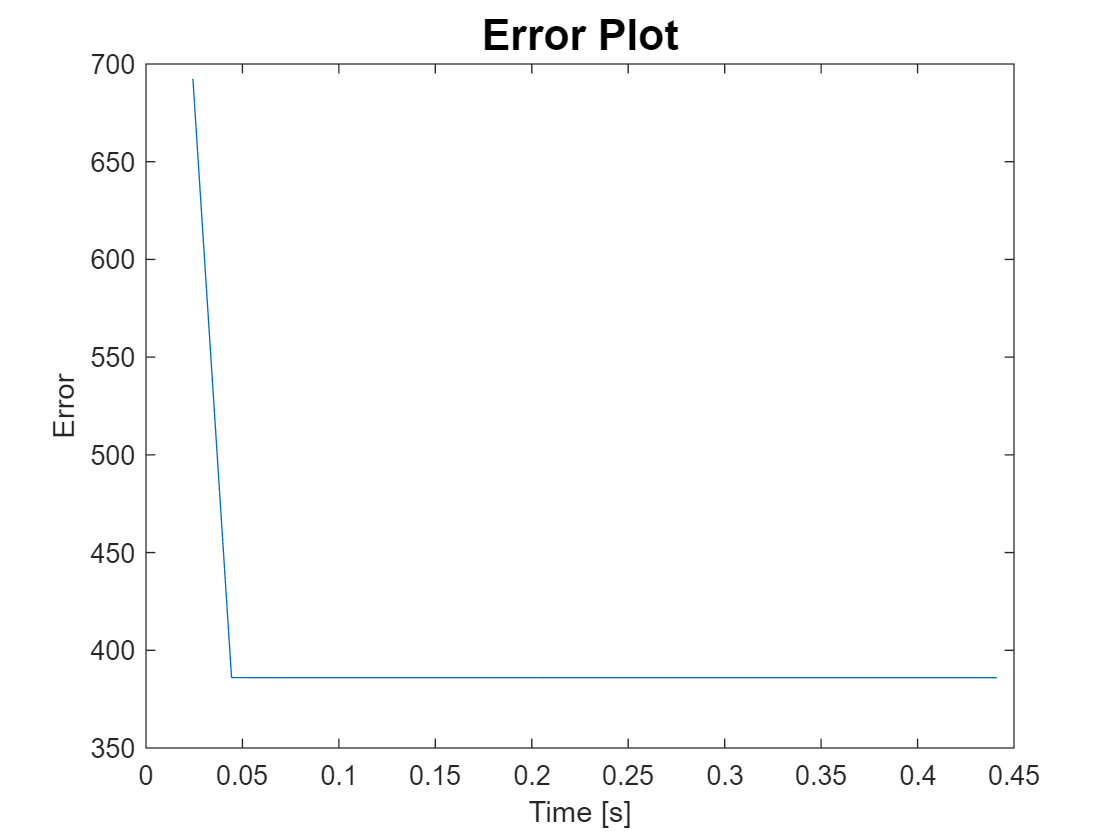

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

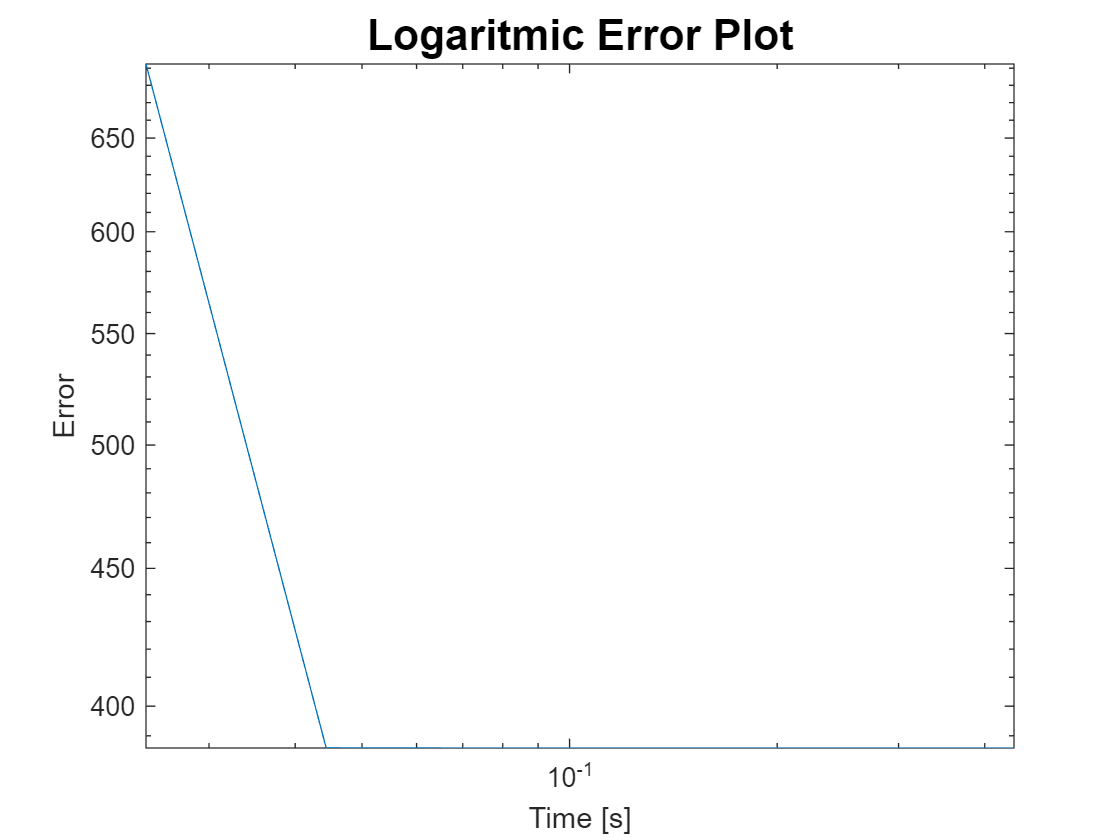

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

## Modified Newton method - 10^4

% Dimension n (multiple of 4)
n = 10^4;  % 10^4;

% Initializations
f = @(x) 0;
x0 = zeros(n, 1);

% Chained Wood function
for j = 1 : (n - 2)/2
    f_1 = @(x) 100*(x(2*j-1, :).^2 - x(2*j, :)).^2 + ...
        (x(2*j-1, :) - 1).^2 + ...
        90*(x(2*j+1, :).^2 - x(2*j+2, :)).^2 + ...
        (x(2*j+1, :) - 1).^2 + ...
        10*(x(2*j, :) + x(2*j+2, :) - 2).^2  + ...
        (1/10)*(x(2*j, :) - x(2*j+2, :)).^2;  % Wood function (j=1)
    f = @(x) f(x) + f_1(x);  % Chained Wood function
end

% Starting point x0 (more easy)
x0 = 2*ones(1, n)';

% Expected solution
x_sol = ones(1, n)'; 

% Gradient
gradf = @(x) chainedwood_grad(x);

### Parameters

kmax = 100;  % maximum number of iterations
step_k = 5;  % step between one iteration and the successive to memorize efficiently the orders fo convergence and the errors;
tolgrad = 1e-8;  % stopping criterion w.r.t. the norm of the gradient
c1 = 1e-1;  % factor of the Armijo condition
rho = 0.1;  % fixed factor used for reducing alpha0
btmax = 800;  % ﻿maximum number of steps for updating alpha
parameters = table(kmax, step_k, tolgrad, c1, rho, btmax)

parameters = 1×6 table
    kmax    step_k    tolgrad    c1     rho    btmax
    ____    ______    _______    ___    ___    _____

    100       5        1e-08     0.1    0.1     800 


Hessf = @(x) 0;
FDgrad = 1;  % 'otherwise' case of "findiff_grad"
FDHess = 'Jc';
h = 0.01;  % sqrt(eps)*norm(x0);
[xk, fk, gradfk_norm, k, big_k, err_fseq, ordconv_seq, ...
    totalTimeCost, timeCostseq] = modnewton_bcktrck(x0,x_sol,f,gradf,...
    Hessf,step_k,kmax,tolgrad,c1,rho,btmax, FDgrad, FDHess, h);

*** Tolerance is not respected ***

results_0 = table(xk, x_sol);
head(results_0, 8)

ans = 8×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  


tail(results_0, 8)

ans = 8×2 table
    xk    x_sol
    __    _____

    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  
    1       1  


gradfk_norm_x0 = norm(gradf(x0));
gradfk_norm_inf = norm(gradf(xk), "inf");
errf_final = err_fseq(end);
results_1 = table(fk, k, gradfk_norm_x0, gradfk_norm, gradfk_norm_inf, errf_final, totalTimeCost)

results_1 = 1×7 table
        fk        k     gradfk_norm_x0    gradfk_norm    gradfk_norm_inf    errf_final    totalTimeCost
    __________    __    ______________    ___________    _______________    __________    _____________

    2.8824e-20    13        21722         6.5414e-10       2.0779e-10       2.4571e-08       0.23263   


err_fseq = err_fseq';
ordconv_seq = ordconv_seq';
timeCostseq = timeCostseq';
results_2 = table(err_fseq, ordconv_seq, timeCostseq);
head(results_2, 8)

ans = 2×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        58.788      1.6662          0.1262  
    2.4571e-08      1.2123         0.23263  


tail(results_2, 8)

ans = 2×3 table
     err_fseq     ordconv_seq    timeCostseq
    __________    ___________    ___________

        58.788      1.6662          0.1262  
    2.4571e-08      1.2123         0.23263  


plot(1:big_k, err_fseq)
title('Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

loglog(1:big_k, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('k')
ylabel('Error')

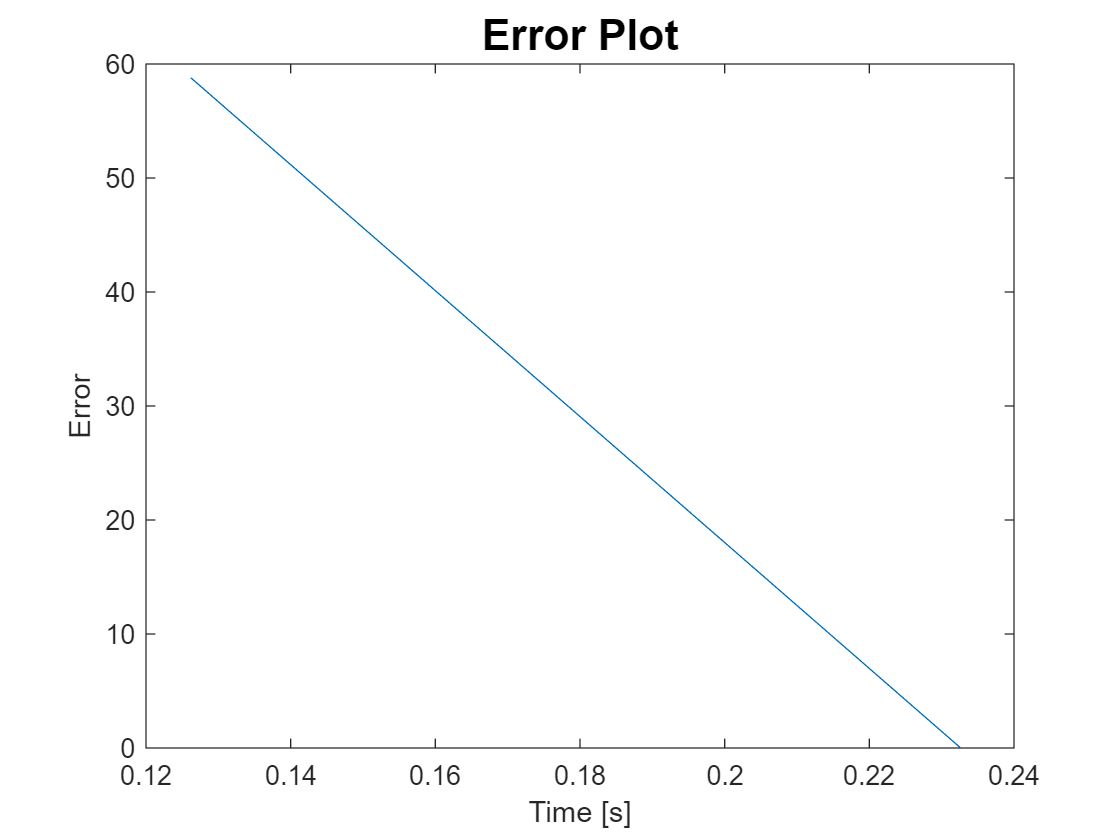

plot(timeCostseq, err_fseq)
title('Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')

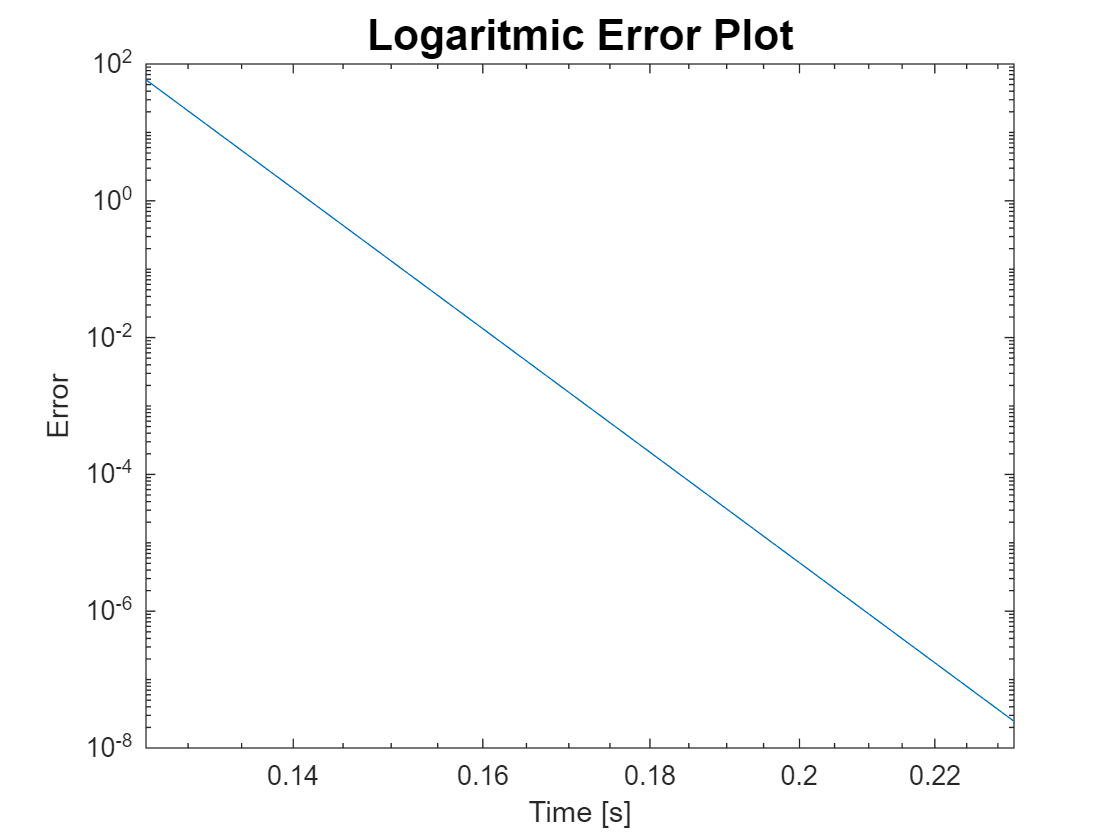

loglog(timeCostseq, err_fseq)  % base-10 logarithmic scale on the x-axis and the y-axis
title('Logaritmic Error Plot','FontSize',16)
xlabel('Time [s]')
ylabel('Error')